### Removing Power Line Interference of 50Hz Using IIR Notch Filter 

clc;
clear all;
close all;

%Loaded ECG Signal
load('100m.mat')

%Removing the Base and Gain from ECG Signal
ECGsignal_original = (val -1024)/100;
Fs = 360;

%Frequency of PowerLine Interference
f1 = 50;   

t = (0:length(ECGsignal_original)-1)/Fs;

%Generating Noise for f1 = 50 Hz
N= 0.1*cos (2*pi*f1*t);

%Adding Noise to ECG signal
ECG_Noise = ECGsignal_original + N;

% Designing_IIR_Notch_Filter_using_coefficient
num = 0.957*[1 -1.2844 1];
den = [1 -1.2291 0.914];
sys = tf(num,den);
[Z,P,K] = tf2zp(num,den)

Z =    0.6422 + 0.7665i
   0.6422 - 0.7665i


P =    0.6146 + 0.7323i
   0.6146 - 0.7323i


K = 0.9570

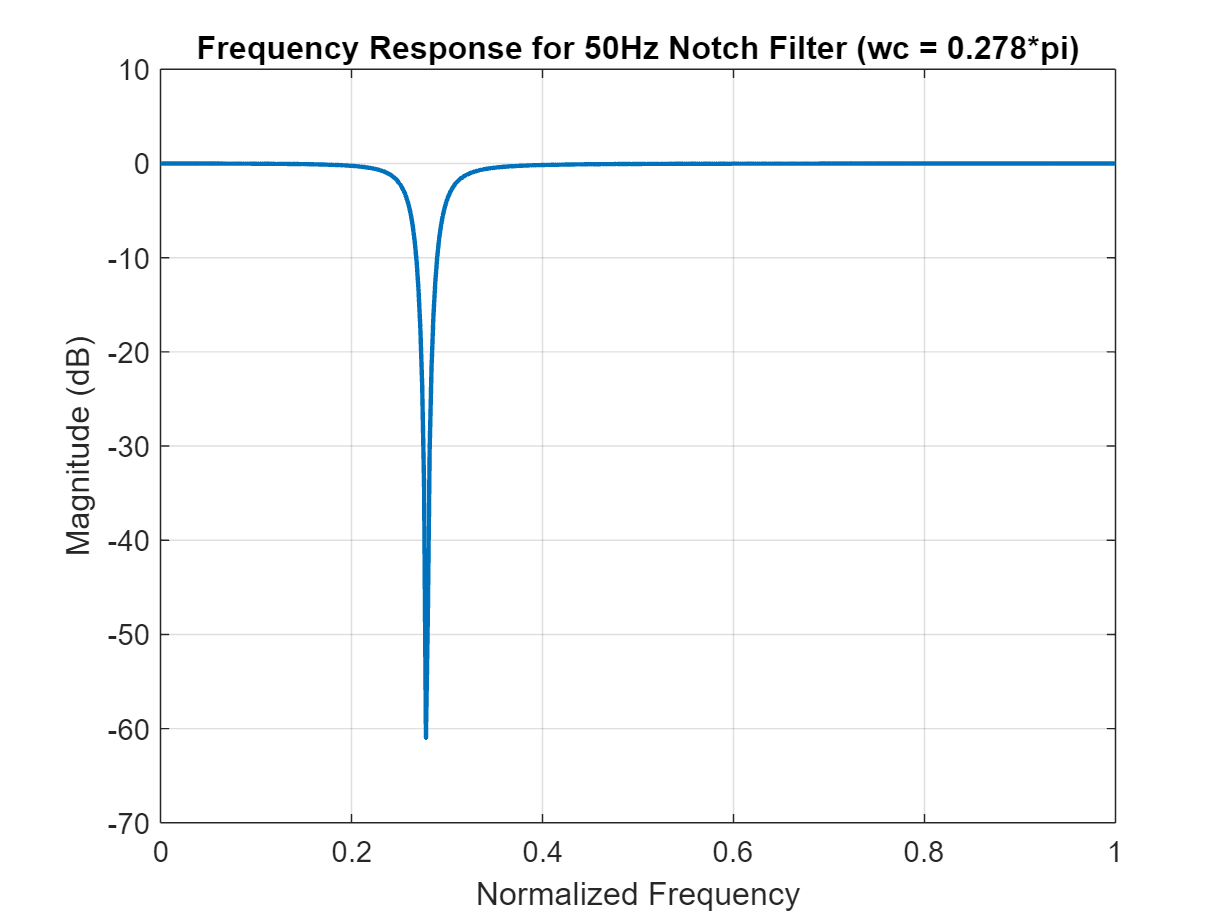

%Freq response of filter
[H,w]=freqz(num,den);
plot(w/max(w),20*log(abs(H)),LineWidth=1.5)
xlabel('Normalized Frequency')
ylabel('Magnitude (dB)')
title('Frequency Response for 50Hz Notch Filter (wc = 0.278*pi)')
grid on

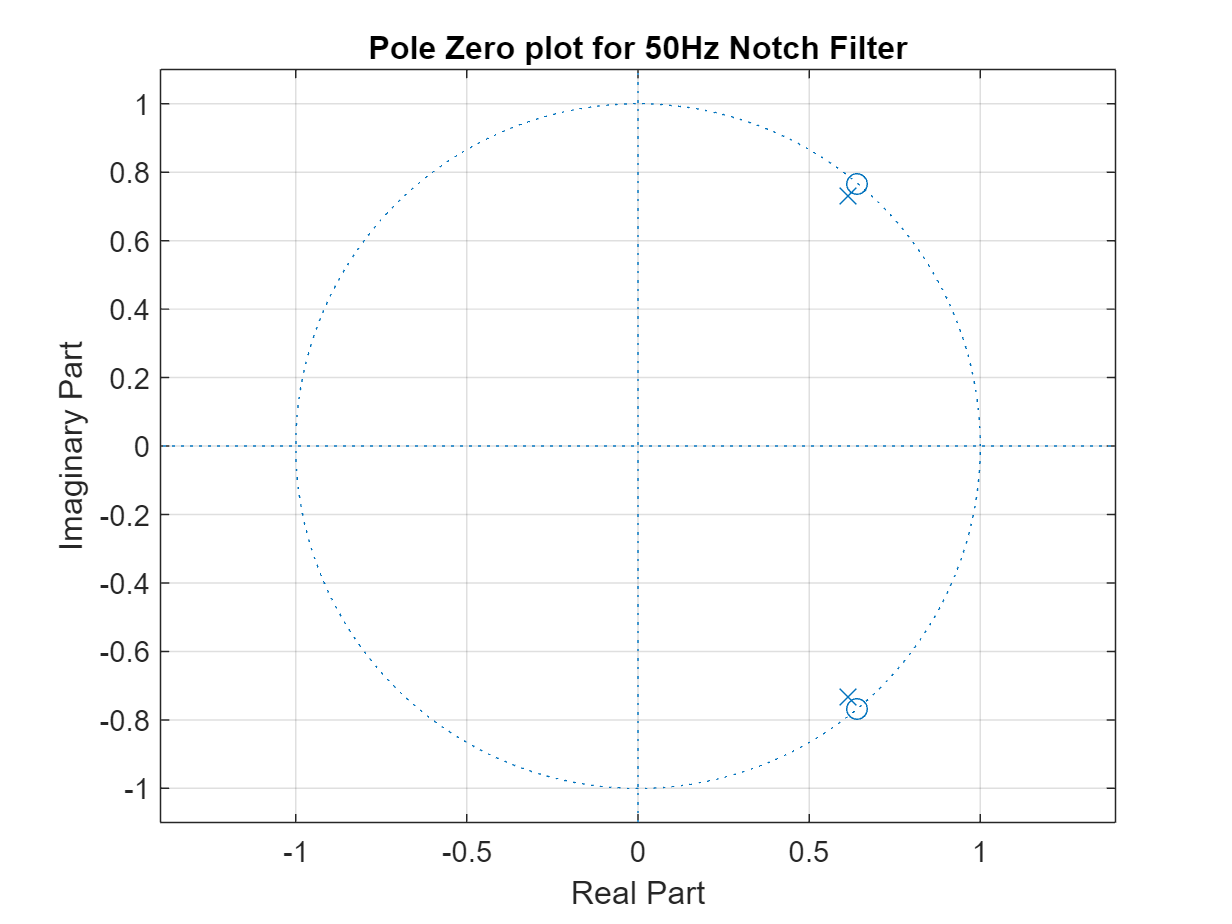

%Pole Zero plot of filter
zplane(num,den);
title('Pole Zero plot for 50Hz Notch Filter')
grid on

%Reconstructed ECG Signal using Designed Filter
ecg_recons = filter(num,den,ECG_Noise);

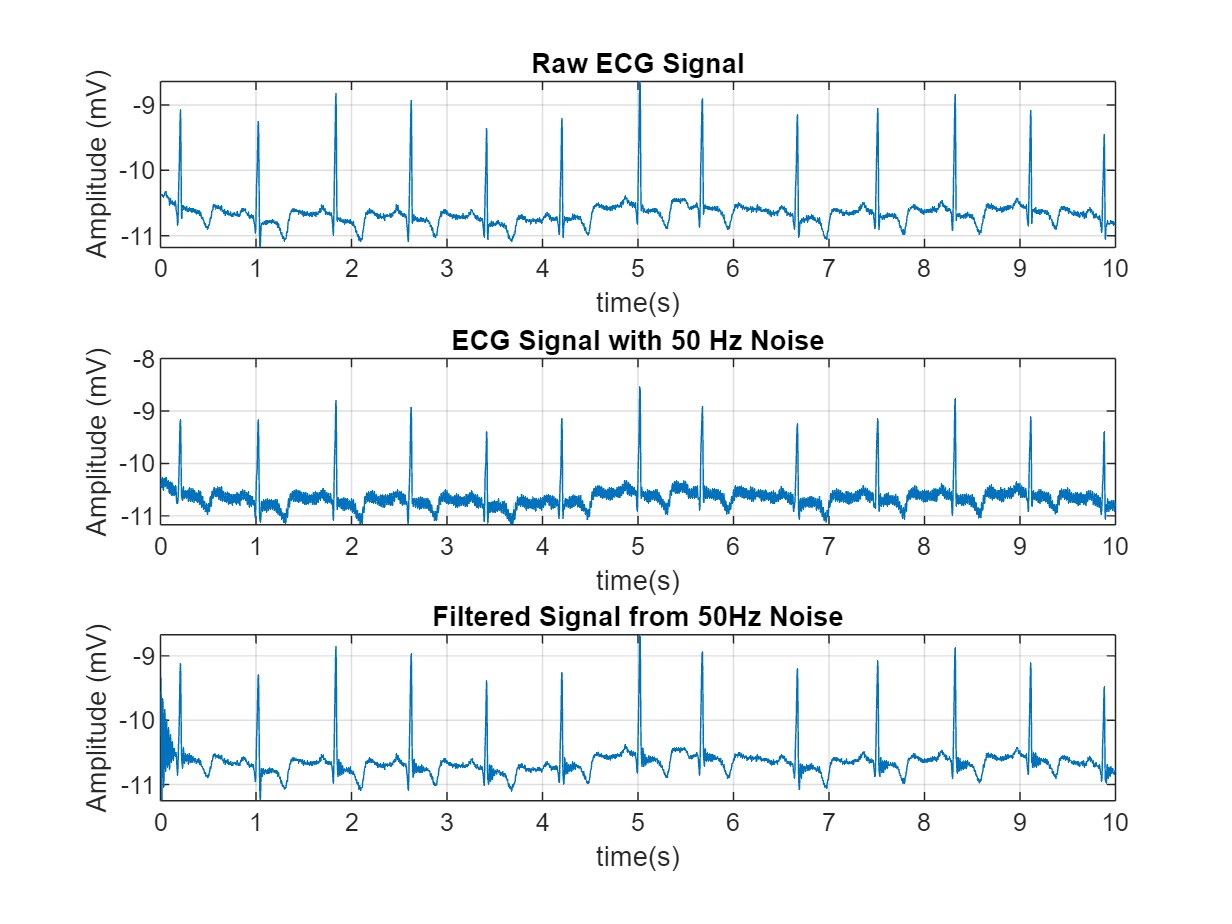

subplot(3,1,1)
plot(t,ECGsignal_original)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Raw ECG Signal')
grid on
subplot(3,1,2)
plot(t,ECG_Noise)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('ECG Signal with 50 Hz Noise')
grid on
subplot(3,1,3)
plot(t,ecg_recons)
xlabel('time(s)')
ylabel('Amplitude (mV)')
title('Filtered Signal from 50Hz Noise')
grid on